visualisation of data

% histogram(y(1,:),5)52

normalization and data collection

clear all
totaldata=xlsread('normalisedtrainingdata.xlsx','sheet2');
y=totaldata(:,6);
x=totaldata(:,1:5);
% indx=randsample(1:length(x),5);
% z=x(indx,:);
% zt=z';
xt=x';
yt=y';
% for i=1:15
%     xt(i,:)=(x(i,:)-min(x(i,:)))/(max(x(i,:))-min(x(i,:)));
% end
% for i=1:5
%     yt(i,:)=(y(i,:)-min(y(i,:)))/(max(y(i,:))-min(y(i,:)));
% end

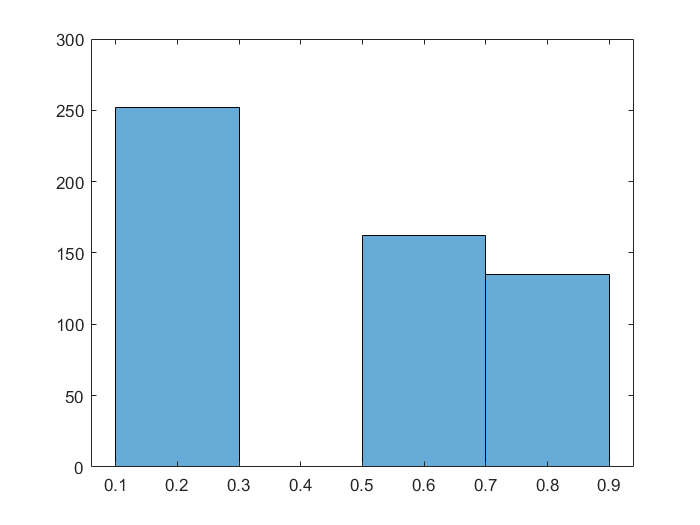

histogram(yt(1,:),4)

trinning the data

net = fitnet([60 60],'trainlm');
[net,tr] = train(net,xt,yt);
% view(net);
 invnatfreq2000=net; 
  save('invnatfreq2000.mat')

performance

yttrain=net(xt(:,tr.trainInd));

Unable to resolve the name tr.trainInd.

yttraintrue=yt(:,tr.trainInd);
% for i=1:15
%     yttrain(i,:)=ytrain(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
% for i=1:15
%     yttraintrue(i,:)=ytraintrue(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
RMSETRAIN=sqrt(mean((yttrain'-yttraintrue').^2))
ytval=net(xt(:,tr.valInd));
ytvaltrue=yt(:,tr.valInd);
% for i=1:15
%     ytval(i,:)=yval(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
% for i=1:15
%     ytvaltrue(i,:)=yvaltrue(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
RMSEVAL=sqrt(mean((ytval'-ytvaltrue').^2))
yttest=net(xt(:,tr.testInd));
yttesttrue=yt(:,tr.testInd);
% for i=1:15
%     yttest(i,:)=ytest(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
% for i=1:15
%     yttesttrue(i,:)=ytesttrue(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
RMSETEST=sqrt(mean((yttest'-yttesttrue').^2))

R2 value

Rtrain2=1-(sum((yttrain'-yttraintrue').^2)./sum(yttrain'.^2));
Rval2=1-(sum((ytval'-ytvaltrue').^2)./sum(ytval'.^2));
Rtest2=1-(sum((yttest'-yttesttrue').^2)./sum(yttest'.^2));
% MAPETRAIN=100*(mean((yttraintrue'-yttrain')./yttraintrue'));
% MAPEVAL=100*(mean((ytvaltrue'-ytval')./ytvaltrue'));
% MAPETEST=100*(mean((yttesttrue'-yttest')./yttesttrue'));

plotting result

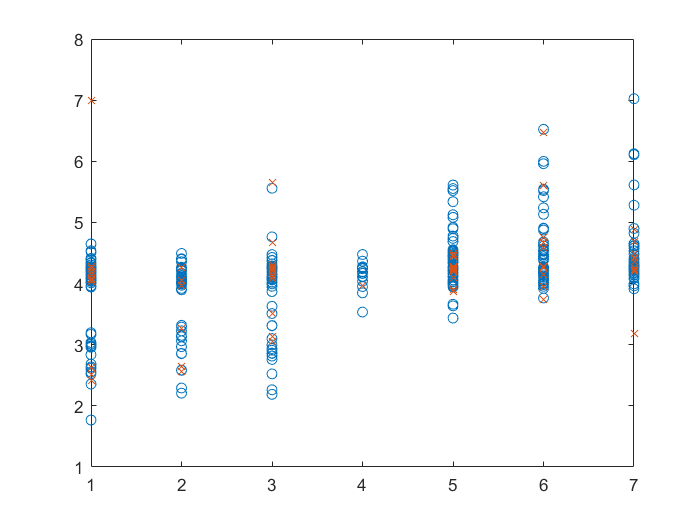

for i=1:8
    plot(yttraintrue(i,:),yttrain(i,:),'o'); hold on;
    plot(yttesttrue(i,:),yttest(i,:),'x'); hold off;
end

optimal neuron

for k=1:60
net = fitnet([k k],'trainlm');
[net,tr] = train(net,xt,yt);
yttrain=net(xt(:,tr.trainInd));
yttraintrue=yt(:,tr.trainInd);
% for i=1:8
%     yttrain(i,:)=ytrain(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
% for i=1:8
%     yttraintrue(i,:)=ytraintrue(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
RMSEtrain(k,:)=sqrt(mean((yttrain'-yttraintrue').^2));
ytval=net(xt(:,tr.valInd));
ytvaltrue=yt(:,tr.valInd);
% for i=1:8
%     ytval(i,:)=yval(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
% for i=1:8
%     ytvaltrue(i,:)=yvaltrue(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
RMSEval(k,:)=sqrt(mean((ytval'-ytvaltrue').^2));
yttest=net(xt(:,tr.testInd));
yttesttrue=yt(:,tr.testInd);
% for i=1:8
%     yttest(i,:)=ytest(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
% for i=1:8
%     yttesttrue(i,:)=ytesttrue(i,:).*(max(y(i,:))-min(y(i,:)))+min(y(i,:));
% end
RMSEtest(k,:)=sqrt(mean((yttest'-yttesttrue').^2));   
end

ploting result

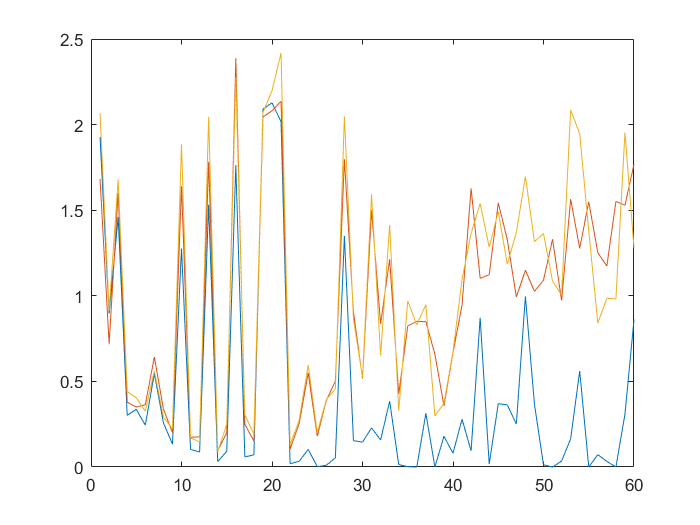

plot(1:60,RMSEtrain(:,1)); hold on;
plot(1:60,RMSEval(:,1)); hold on;
plot(1:60,RMSEtest(:,1)); hold off